# Getting Started with Volume Labeling Widgets - MATLAB App Building Components

*Copyright 2018-2021 The MathWorks, Inc.*

## Description

Volume Labeling Widgets enable advanced GUI programmers to efficiently develop advanced MATLAB apps to implement common medical image processing workflows. The toolbox provides specialized components that implement the building blocks for visualizing and labeling image stacks and 3D isosurfaces resulting from image segmentation.

## Features

Widgets provided in this toolbox include:

- Image Stack / Volume Visualization and Annotation Labeling

- Isosurface Visualization and Annotation Labeling

- Slice Plane (X/Y/Z) visualization

Additionally included are sample apps for:

- Interactively labeling points, lines, polygons, and masks on an image stack volume

- Interactively labeling points, lines, polygons, and planes on a 3D isosurface

## System Requirements

- MATLAB R2020b or later is required. 

- Widgets created from this toolbox must be placed into a uifigure.

## Examples

This toolbox does not have full documentation but is demonstrated by examples. To view the example live scripts, please browse to the toolbox installed directory under the folder "demo".  You can change MATLAB's current directory to that folder by [clicking here](matlab:cd(fileparts(which('demoVolumeViewer.mlx')))).

## Visualizing a Volume by Slice

To start, we need a figure. Return the figure handle as `f` so we can place the widget.

f = figure;

Now we can add a widget to our figure:

viewer = wt.VolumeViewer('Parent',f);

To add some data, the imagery needs to be placed inside a VolumeModel object. This VolumeModel object manages the raw data and related properties.

% Load a dataset
load('mristack.mat','mristack');

% Place the data into a VolumeModel
volModel = wt.model.VolumeModel('ImageData',mristack);

Now we need to provide the VolumeModel to the viewer:

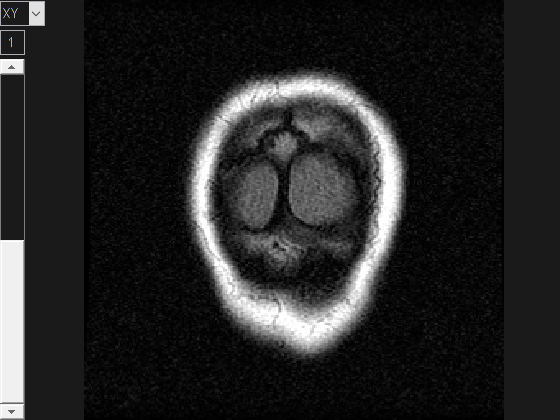

viewer.VolumeModel = volModel;

## Visualizing Slice Planes

Visualizing slice planes is very similar to visualizing a volume by slice, except you see one slice in each of the 3 dimensions.

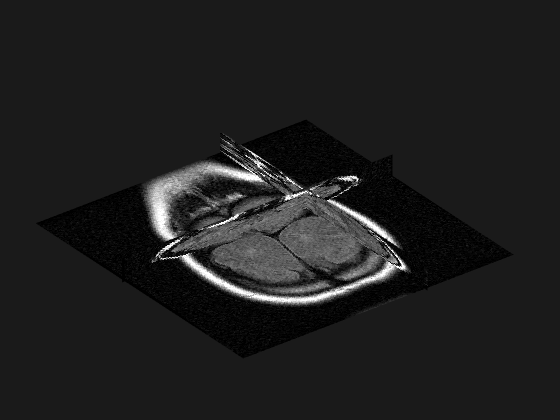

f = figure;
viewer2 = wt.SlicePlaneViewer('Parent',f,'VolumeModel',volModel,'Slice',[150 175 3]);

This is most useful when building an app where you may have multiple views side-by-side (XY, YZ, XZ planes) and need to be able to see where you are in the volume.

## Visualizing an Isosurface

You may also visualize an Isosurface. First you need to load in data and create an IsosurfaceModel:

s = load('mri.mat');
data = squeeze(s.D);

% Create isosurface
isovalue = 40;
[faces, vertices] = isosurface(data, isovalue);
voxel_size  = [1 1 3];
vertices    = vertices .* voxel_size;
vertexNormals = isonormals(data,vertices);

% Place into an IsosurfaceModel
isoModel = wt.model.IsosurfaceModel(...
    'Faces',faces,...
    'Vertices',vertices,...
    'VertexNormals',vertexNormals);

Now we can create the viewer:

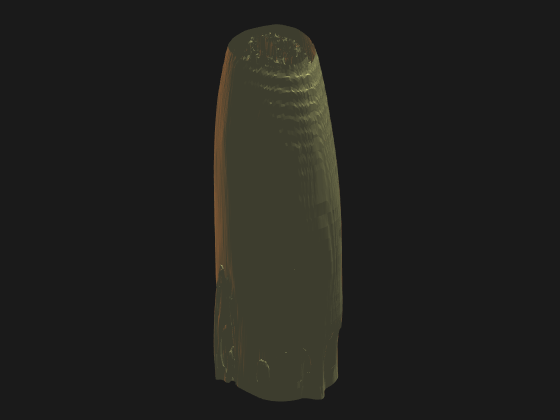

f = figure;
viewer3 = wt.IsosurfaceViewer('Parent',f,'IsosurfaceModel',isoModel);

There is also a capability to annotate an isosurface in 3D using an AnnotatedIsosurfaceViewer. This is not discussed in the getting started guide.

## Labeling / Annotating a Volume

It is also possible to annotate a volume slice-by-slice.

f = figure;
viewer4 = wt.VolumeLabeler('Parent',f,'VolumeModel',volModel);

First you need to go to the slice you want, either using the scroll bar or programmatically:

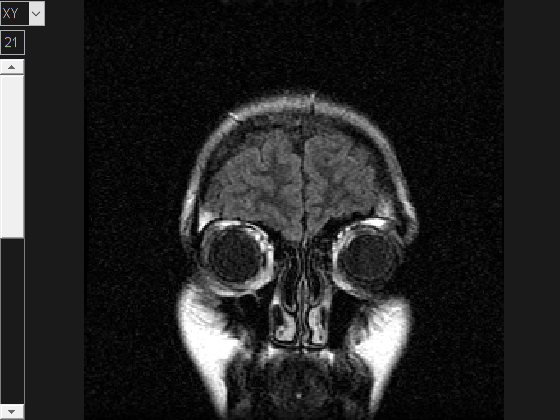

viewer4.Slice = 21;

### Working With Annotations

#### Adding Annotations Interactively

If you want to interactively create a line annotation by clicking, call this:

line1 = wt.model.LineAnnotation('Color',[0 1 0]);
viewer4.addInteractiveAnnotation(line1);

You then may click points on the imagery, and if needed use the scrollbar to change slices.  For demonstration purposes, let's add a few points programmatically and assume you clicked on these locations:

line1.addPoint([67 134 21])
line1.addPoint([145 134 21])
line1.addPoint([210 134 21])

When you want to complete the annotation, you may either double-click the mouse to place the last point, or you may programmatically end the interactive annotation mode:

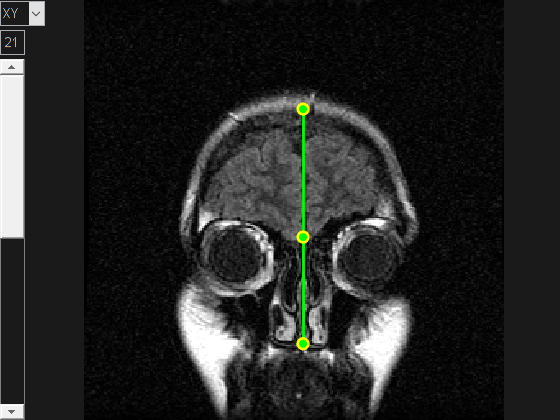

viewer4.finishAnnotation

#### Adding Annotations Programmatically

Additional annotations may be added programmatically as well:

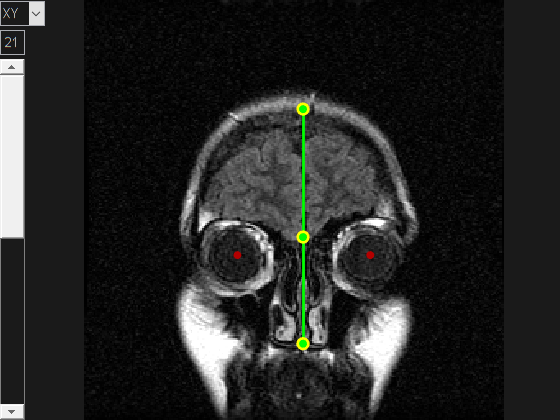

points = [
    156  94 1
    156 175 1];
points1 = wt.model.PointsAnnotation('Color',[1 0 0],'Points',points);
viewer4.addAnnotation(points1);

#### Changing the Selected Annotation

Note that this annotation is in a different Z-slice within the XY plane, so it appears dimmed in the view. It will appear brighter if you do any of these things:

- Scroll to that slice

- Programmatically change slice

- Click on the annotation points to select it

- Programmatically select it

Let's try programmatically selecting it:

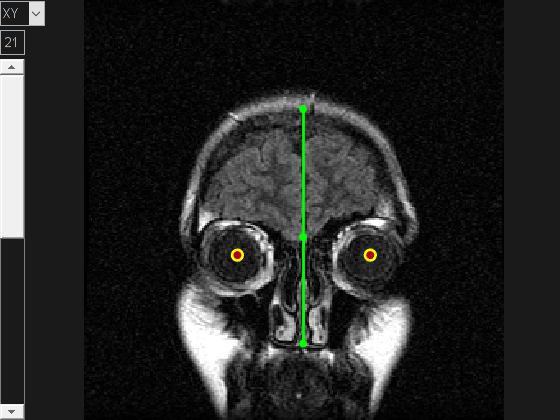

viewer4.selectAnnotation(points1);

#### Using a Mask Annotation

You may also display a mask on the annotated volume:

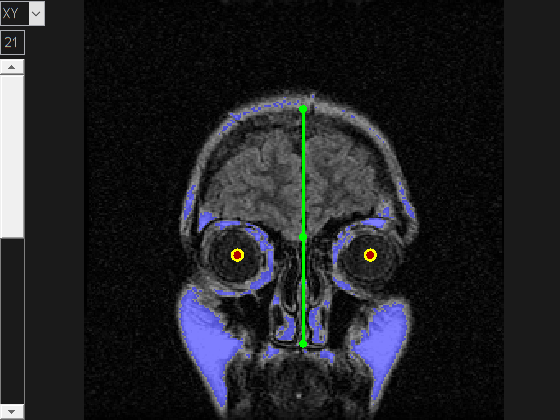

mask1 = wt.model.MaskAnnotation.fromVolumeModel(volModel,...
    'Mask',volModel.ImageData > 150,...
    'Color',[0 0 1],...
    'Alpha',0.5);

viewer4.addAnnotation(mask1);

#### Deleting an Annotation

Annotations may be hidden or removed from the view. To hide an annotation, toggle its visiblity:

mask1.IsVisible = false;

You may request a list of annotation objects from the viewer:

allAnnotations = viewer4.AnnotationModel

allAnnotations =   3×1 Heterogeneous BaseAnnotationModel with common properties:

             Name       Color         Alpha      IsVisible    IsSelected    IsBeingEdited    Tag    UserData                Type                ShowObject    HasLine      Parent      IsBeingDeleted
             ____    ____________    ________    _________    __________    _____________    ___    ________    ____________________________    __________    _______    __________    ______________

You may tell the viewer to remove an annotation:

viewer4.removeAnnotation(points1)

If you forcibly delete the annotation object, it will also be removed:

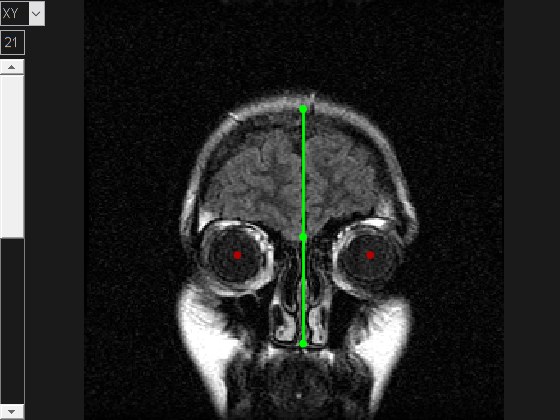

delete(points1)

## Building an App Using Volume Visualization or Annotation Widgets

If you want to build an app using the volume visualization and annotation widgets, you may need to know when the user has changed something. There are two things you can do for this: setting a widget callback and/or listening to changes in the model objects.

### Setting the Widget's Callback

You may add a callback to the viewer. The callback function is specified using a function handle.

For now, the callback will just display the eventdata in the command window. In your actual implementation, replace the `disp` below with the name of your own callback function. 

viewer.Callback = @(h,e)disp(e);

Now interact with the widget. If you change slice, you will see the result in the command window.

### Listening to Model Changes

You can also create a listener to trigger a callback function or method to execute upon changes in the VolumeModel or any type of annotation model.

myListener = event.listener(mask1,'ModelChanged',@(h,e)disp(e) );

Now make a change and see the event data "e", a property change event, is sent to the disp command:

  PropertyChangeEvent with properties:

    AffectedObject: [1×1 uiw.model.MaskAnnotation]
          Property: 'Color'
          NewValue: [0 1 1]
             Error: []
            Source: [1×1 uiw.model.MaskAnnotation]
         EventName: 'ModelChanged'



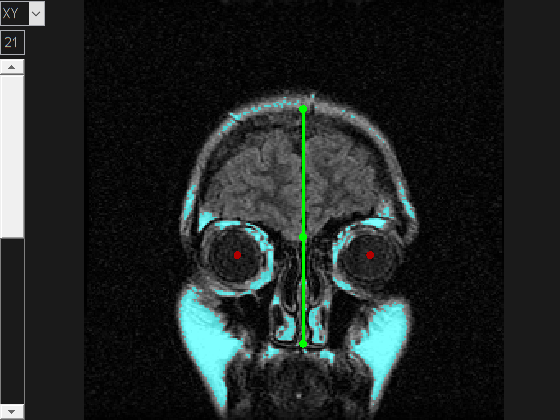

mask1.Color = [0 1 1];

mask1.IsVisible = true;

### 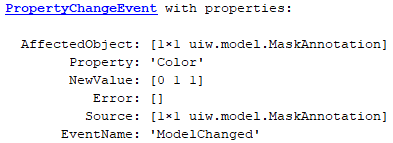

### Special Note: Using Function Handles

Graphics callbacks always provide two input arguments that may be used in your callback function. The first (`h` above) is always the object that was interacted upon, and the second (`e` above) is always the event data about the interaction. 

To create the function handle (right of the `=` above), you always need to define the two default arguments `@(h,e)` before the callback function name. After the function name, you may choose whether or not these inputs get passed in to the function. 

% @(h,e)function(h,e);

You may pass additional arguments into the callback as well. Those additional inputs must be defined in the current workspace when you create the function handle.

If your callback is calling the method of an object, you need to use the object notation that looks like any of these:

% @(h,e)obj.methodname();
% @(h,e)obj.methodname(e);
% @(h,e)obj.methodname(h,e);
% @(h,e)methodname(obj);
% @(h,e)methodname(obj,e);
% @(h,e)methodname(obj,h,e);

© 2019-2020 The MathWorks, Inc.